# Same fish combo - fkg

#### load data

 load("/Users/eric/Documents/MATLAB/fkg.mat");
 load("/Volumes/Elements/hkg.mat"); 

#### save data

 save("/Users/eric/Documents/MATLAB/fkg.mat", "fkg", '-v7.3');
 save("/Volumes/Elements/fkg.mat", 'fkg', '-v7.3');

k = 1    Eugene

% k = 1;
% cd('/Volumes/Elements/Gallman/Same Fish Combos/Eugene40k/');
% fkg(k).e = KatieAssembler('Eigen*',  22);

k = 2;
cd('/Volumes/Elements/Gallman/Same Fish Combos/Eugene20k/');
fkg(k).e = KatieAssembler('Eigen*',  22);

k = 3;
cd('/Volumes/Elements/Gallman/Same Fish Combos/Eugene40koct/');
fkg(k).e = KatieAssembler('Eigen*',  22);

k = 4;
cd('/Volumes/Elements/Gallman/Same Fish Combos/Polka/');
fkg(k).e = KatieAssembler('Eigen*',  23);

k = 5;
cd('/Volumes/Elements/Gallman/Same Fish Combos/Dott/');
fkg(k).e = KatieAssembler('Eigen*',  23);

## plot 

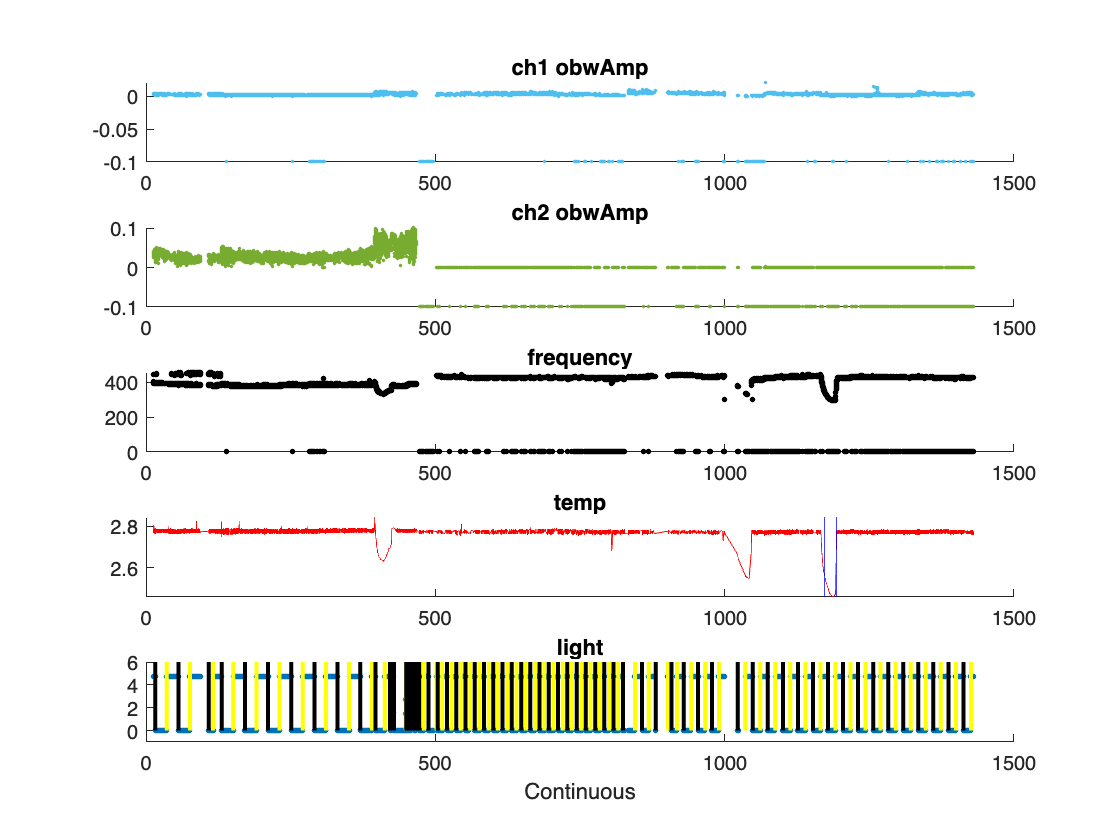

k_initialplotter(fkg(k));

## edits

#### trim data

extra step in case of instant clicking regret...

tempdata = KatieTrimmer(hkg(k).e);

if before was on purpose 

hkg(k).e = tempdata;

#### frequency trimming

Do before outlier removal

extra step in case of instant clicking regret...

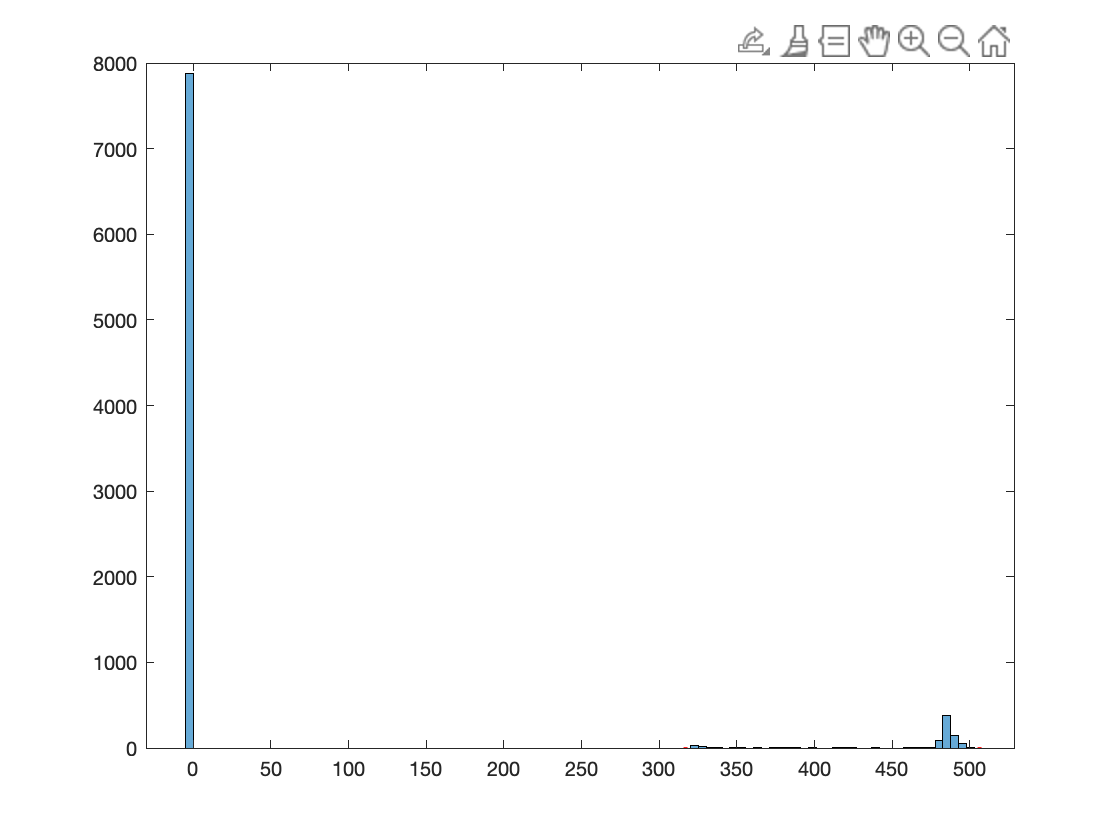

tempdata = KatieFreakyFreqRemover(fkg(k).e);

fkg(k).e = tempdata;

#### Remove outliers

Must be redone after trimming

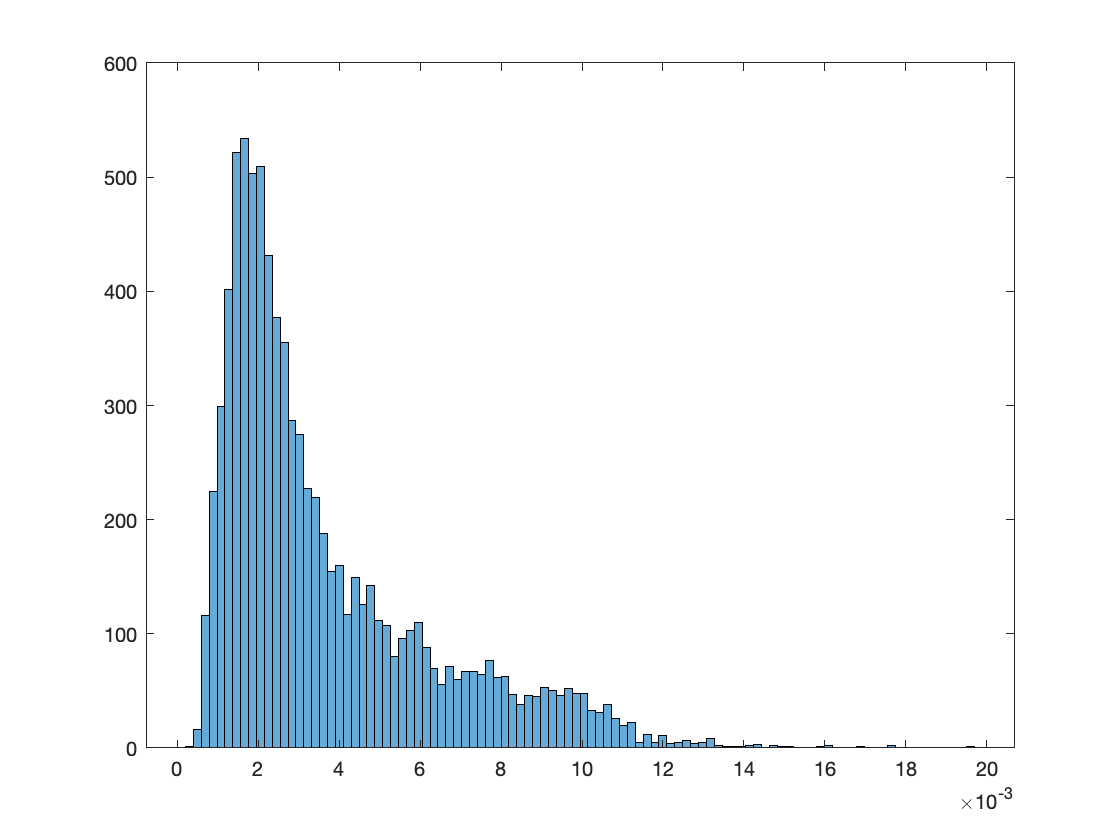

fkg(k).idx = KatieRemover(fkg(k).e);

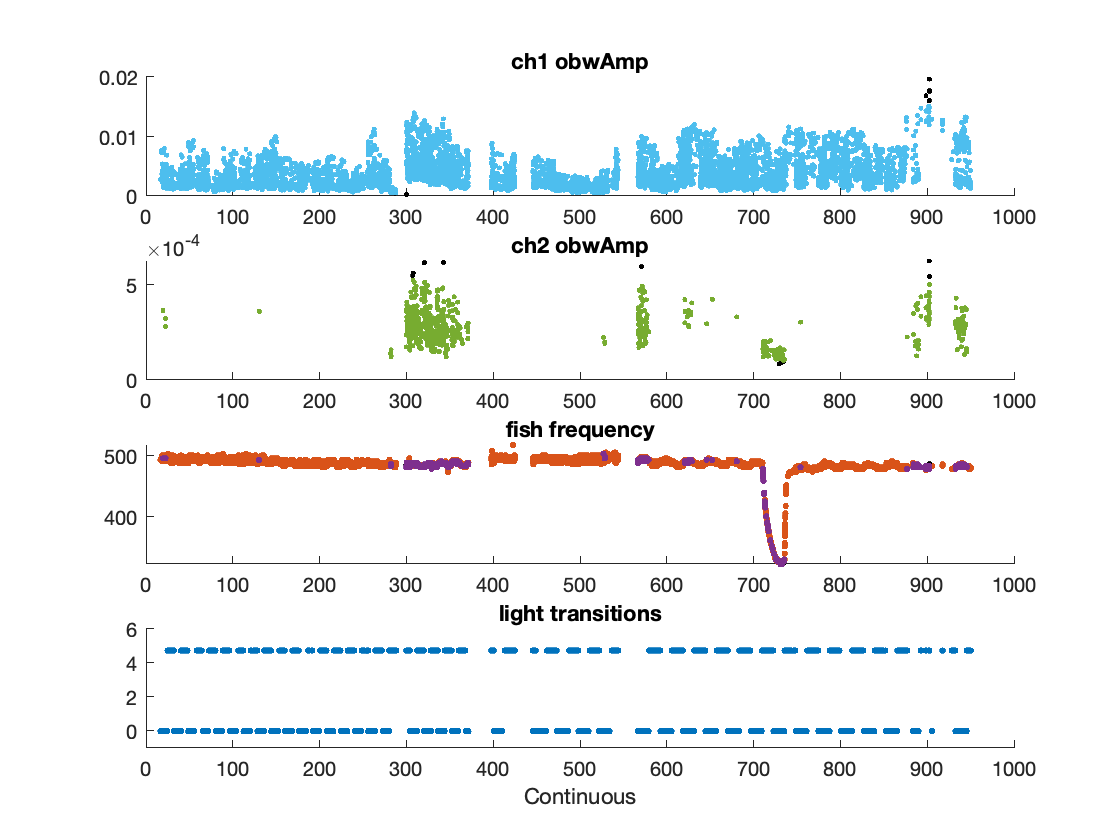

k_removedsingleplotter(fkg(k));

##  plot again

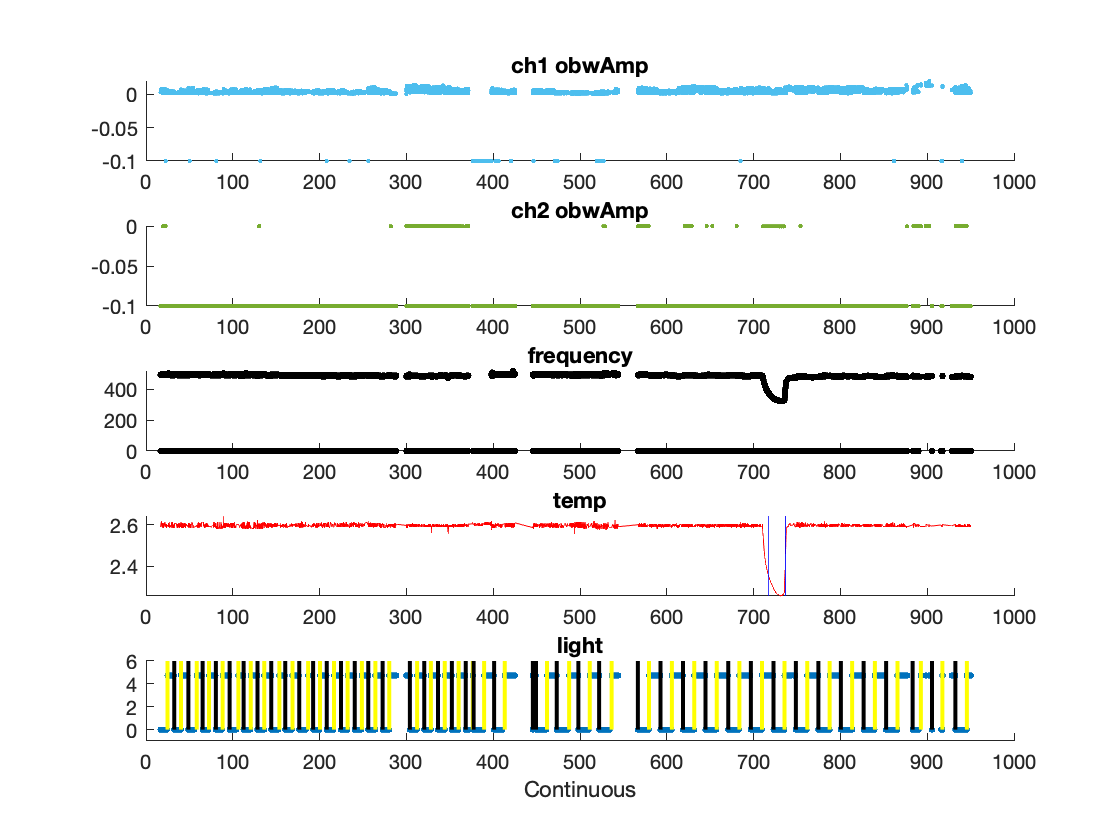

k_initialplotter(fkg(k)); 

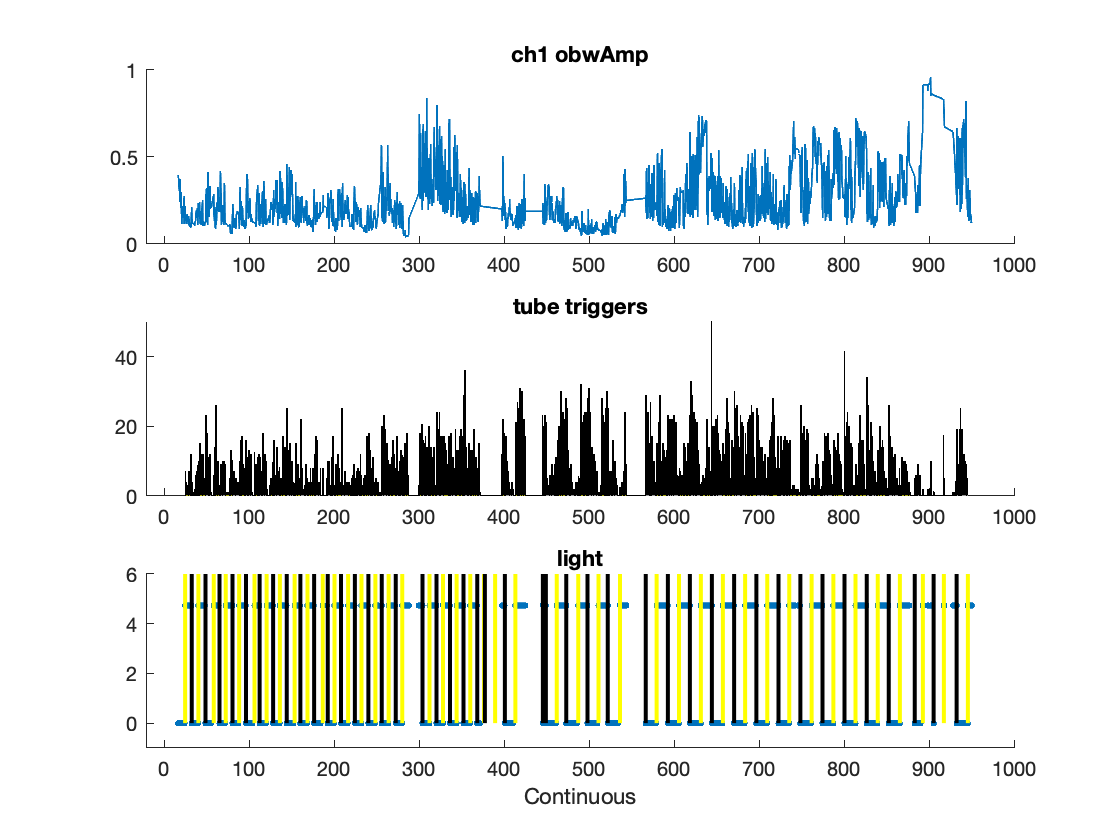

k_ampbinplotter(fkg(k));

## label

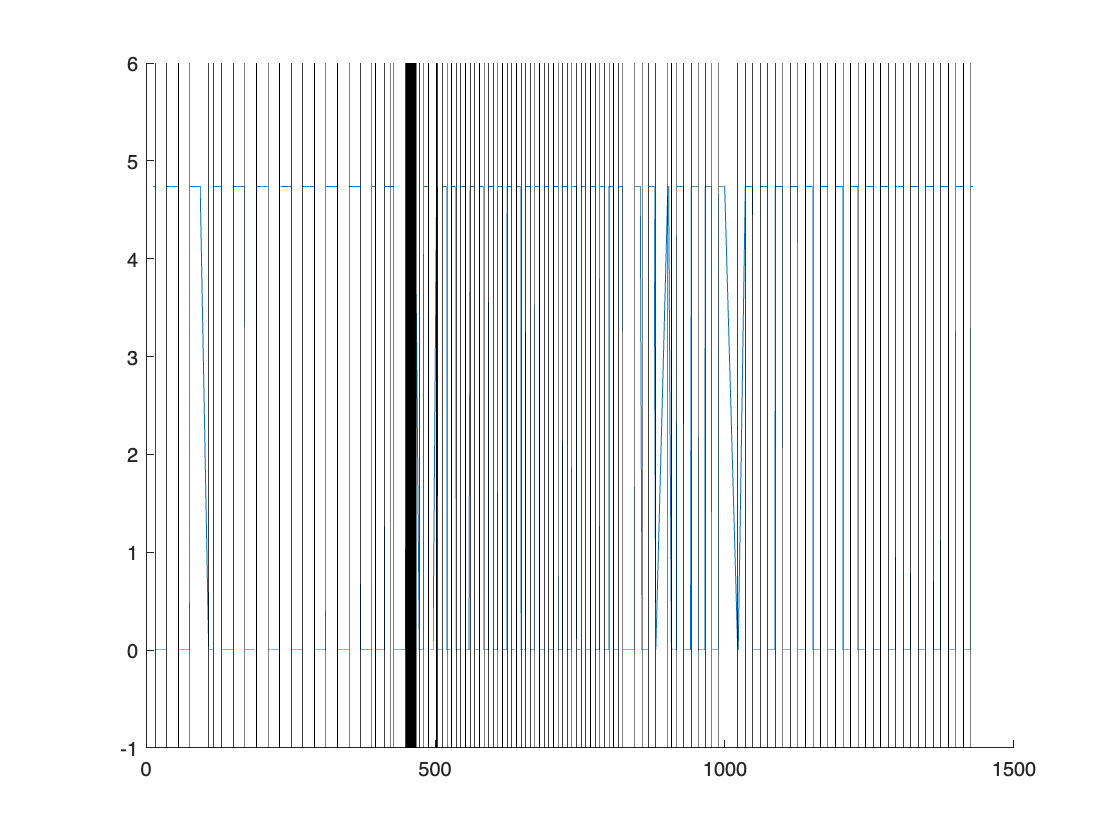

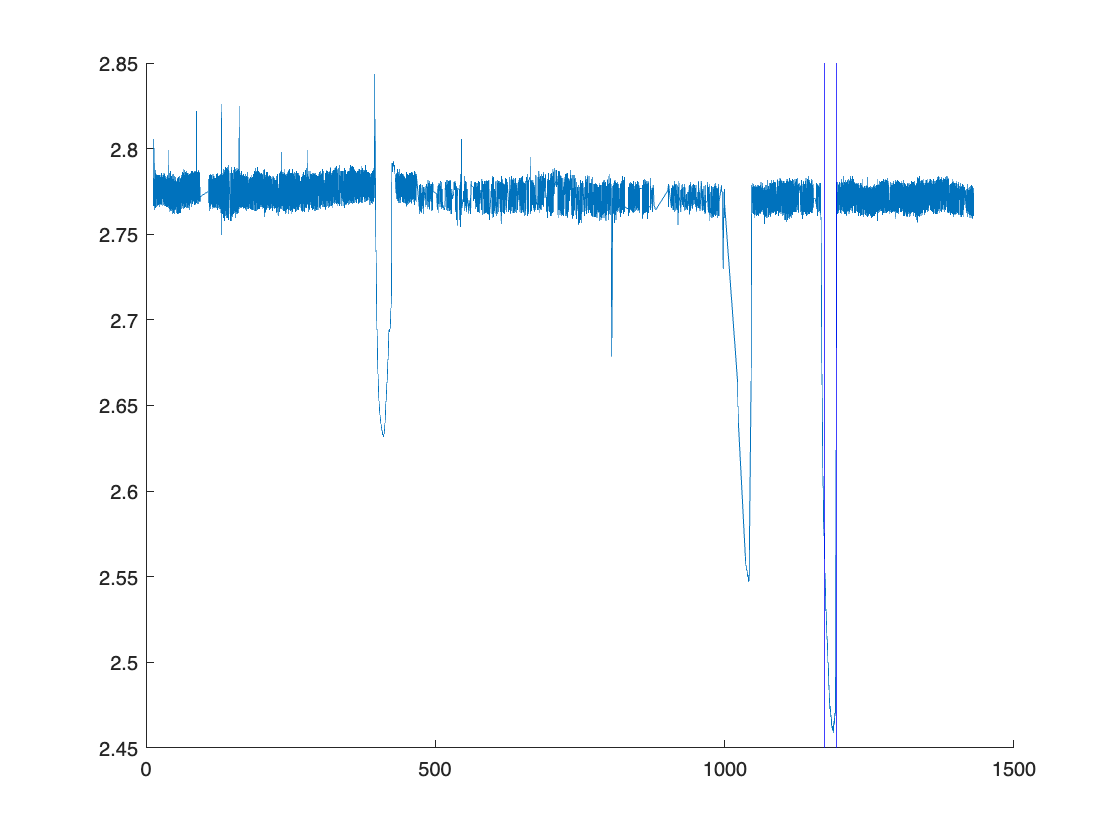

fkg(k).info = KatieTempLabeler(fkg(k).e);

hkg(k).info.luz = k_singlemanuallightlabeler(hkg(k));

lidx = find(abs(hkg(k).info.luz)<200);
hkg(k).info.luz = hkg(k).info.luz(lidx);

channel = 1;
    xidx = find([hkg(k).e(channel).s.timcont]/3600 >113 & [hkg(k).e(channel).s.timcont]/3600 < 125);
    for j = 1:length(xidx)
        if hkg(k).e(channel).s(xidx(j)).obwAmp > 0.085
        hkg(k).e(channel).s(xidx(j)).obwAmp = hkg(k).e(channel).s(xidx(j)).obwAmp;
        end
    end